# Week 7 Exercise 1

clear
close all

Part (a)

## R*dq + q/C = V(t)

R = 100;         % Resistance
C = 0.02;        % Capacitance
q0 = 5;          % Initial Charge on Capacitor
tspan = [0 10];  % Time range

a = 1;
w = 1;
V = @(t) a*sin(w*t);  % Voltage as a function of time

Part (b)

dq1 = @(t,q) (V(t) - q/C)/R;  % Outputs q' as a function of t and q

Part (c)

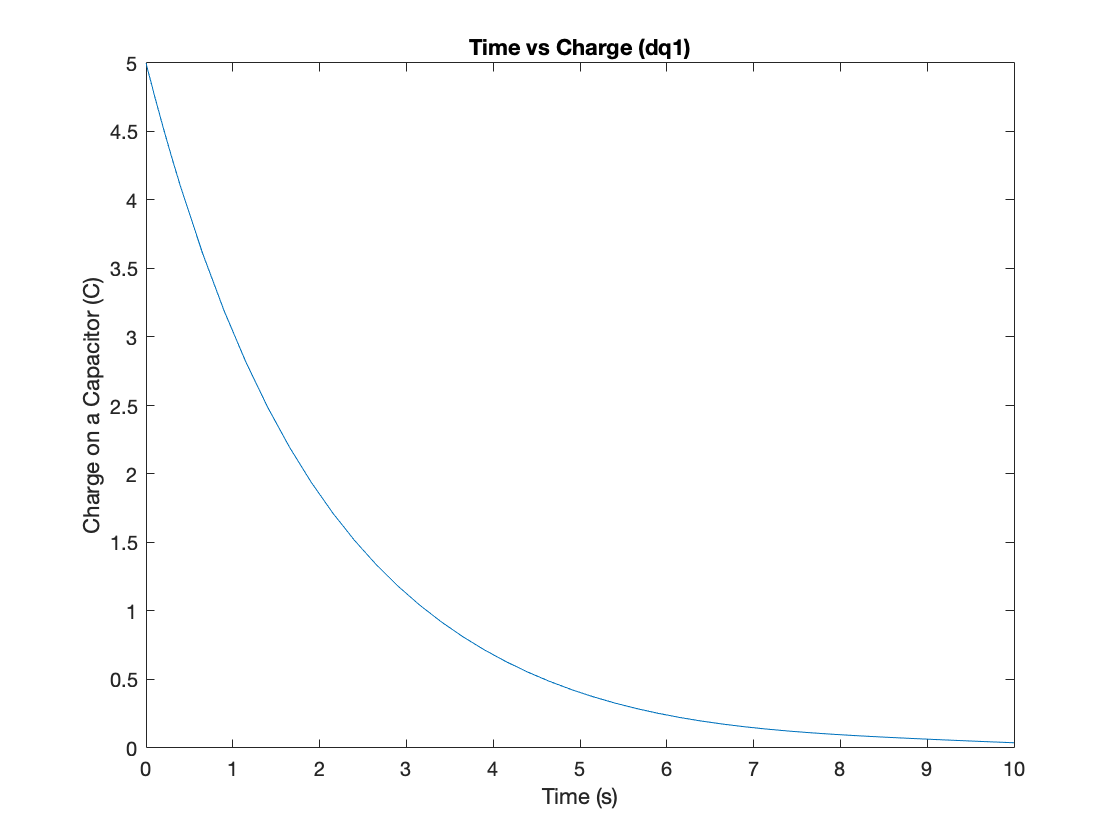

[t, q] = ode45(@(t,q) dq1(t,q), tspan, q0);  % Solving dq1
plot(t,q, 'DisplayName', 'Time vs Charge based on dq1(t,q)')
xlabel('Time (s)')
ylabel('Charge on a Capacitor (C)')
title('Time vs Charge (dq1)')
hold on

Part (d)

dq2 = @(q, V) (V - q/C)/R;  % Outputs q' as a function of q and V

Part (e)

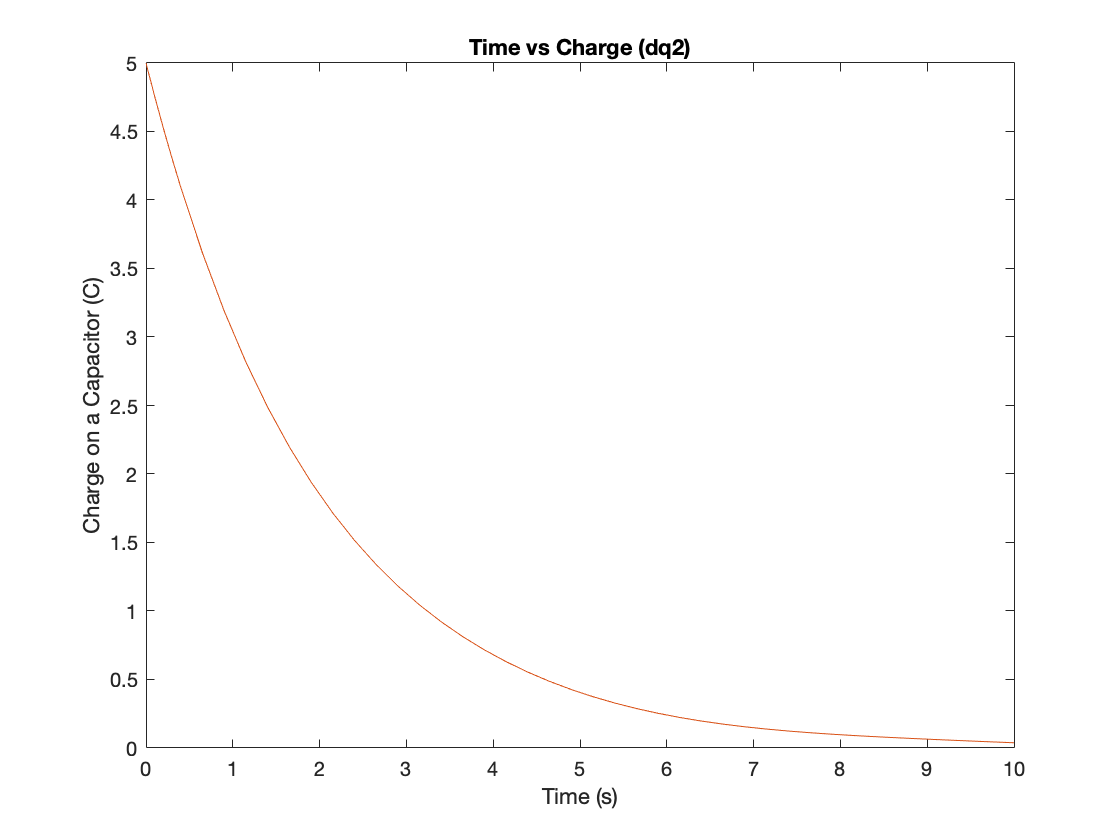

[t, q] = ode45(@(t,q) dq2(q,V(t)), tspan, q0);  % Solving dq2
plot(t,q, 'DisplayName', 'Time vs Charge based on dq2(q,V)')
title('Time vs Charge (dq2)')

Part (f)

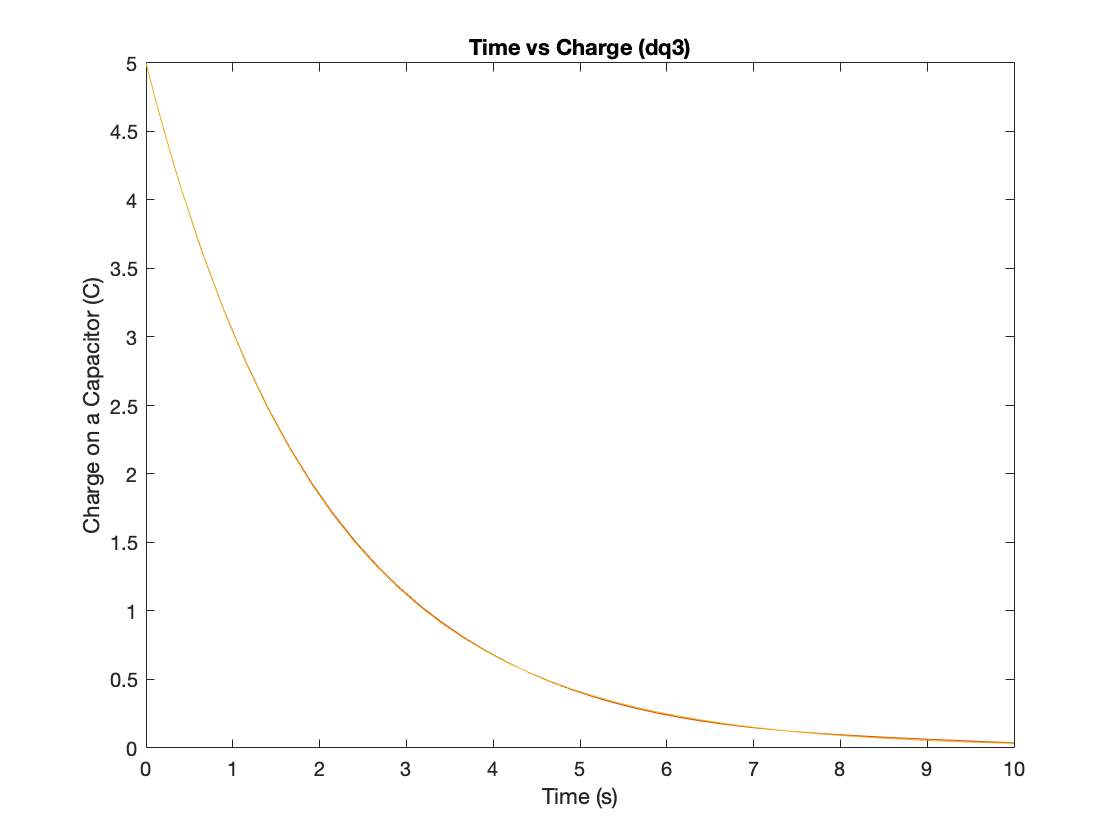

dq3 = @(q) dq2(q,0);  % Outputs q' as a function of q where V(t)=0
[t, q] = ode45(@(t,q) dq3(q), tspan, q0);  % Solving dq3
plot(t,q, 'DisplayName', 'Time vs Charge based on dq3(q)')
title('Time vs Charge (dq3)')

Part (g)

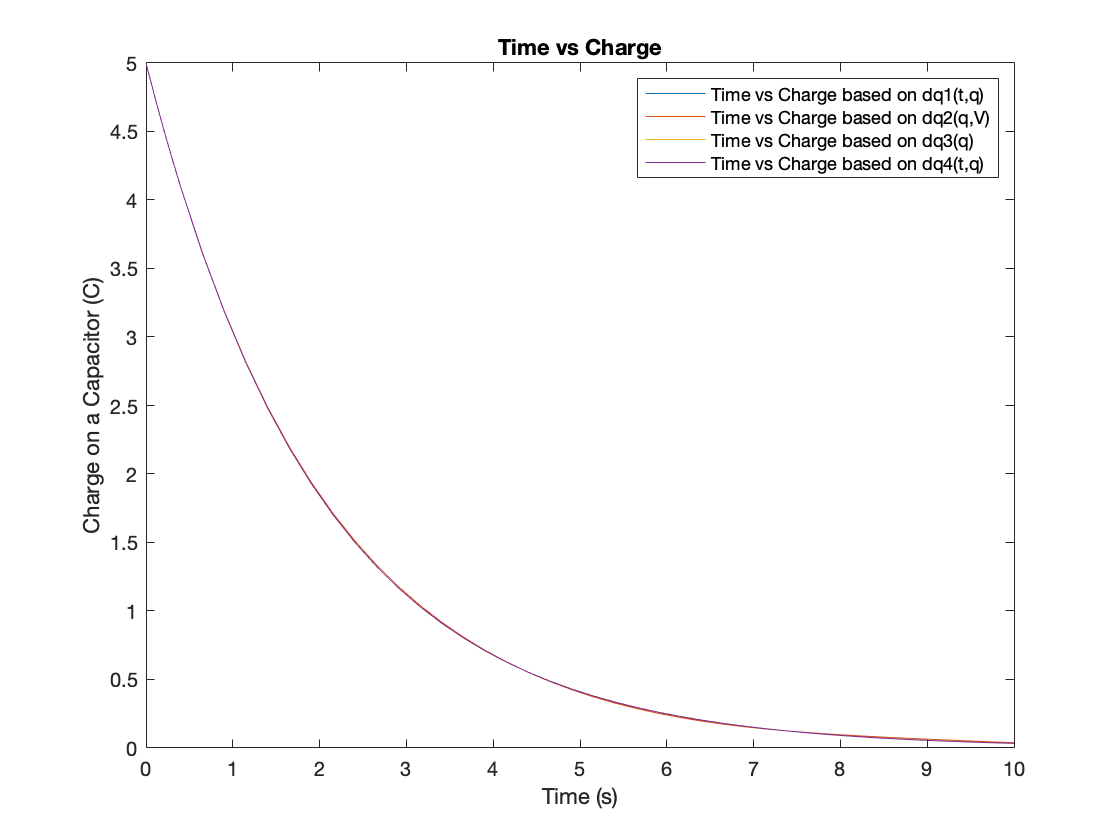

[t, q] = ode45(@(t,q) dq4(q,R,C), tspan, q0);  % Solving dq4 (below)
plot(t,q, 'DisplayName', 'Time vs Charge based on dq4(t,q)')
title('Time vs Charge (dq4)')
legend()
title('Time vs Charge')

function dq = dq4(q,R,C)
    dq = -q/(R*C);  % Outputs q' as a function of t and q
end